clear
% simultion of 6 metagriding

## constants


eta = 377; %ohm
f= 10*10^9; %Hz
c = 3*10^8; %m/s
lambda = c/f;
k = 2*pi/lambda;
omega = 2*pi*f;
w = 3*0.0254e-3; % meters, 3 mil
reff = w/4;
epsilon=8.85e-12;


## paramters


theta_in = 10*pi/180; %rads
theta_out = 70*pi/180;% rads
phi = 25*pi/180; % rads
Ein = 1;

sinin = sin(theta_in);
cosin = cos(theta_in);
sinout = sin(theta_out);
cosout = cos(theta_out);

Zin = eta/cos(theta_in);
Zout = eta/cos(theta_out);
Eout = Ein*sqrt(cosin/cosout);
Lambda = lambda/abs(sinout-sinin);

deltaRes=18.3e-3*eta/lambda; %resistence of copper wire

## Optimization parameters

numOfIter=100;% how maney random starting conditions to check
N=1000; % to what degree to calculate the infinate sums 
weigt=100;%how much to consider power lost and how much 
save('var.mat');
best.Zs=zeros(6,1);% the best results with only capacitance tipe impidances
best.PowerLost=inf;
best.CopperPowerLost=inf;
best.Ds=zeros(1,6);
best.Hs=zeros(1,6);
best.Is=FindCurrents(best.Ds,best.Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);

best.Objective=inf;


## Optimization

i=1; %index
total=0;% for percentage of good ones
while i<=numOfIter 
    total=total+1;
    % initial position
    x0=[Lambda*rand(1,5),lambda*rand(1,5)];
    % Set nondefault solver options
    options = optimoptions('fmincon','Display','off');
        
    % Solve
    [solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
        @constraintFcn,options);
        
    % Clear variables
    clearvars options
    Ds = [0 solution(1:5)];
    Hs = [0 solution(6:10)];
    Is =  FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
    Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
    Zs = Fields./Is;
    objective = objectiveFcn(solution)
    if imag(Zs)<0
         i=i+1%go on with the index
    end
    if objective<best.Objective % is it the best result so far?
            
      if imag(Zs)<0
          best.Objective=objective;
          best.PowerLost=1/2*(abs(Is).^2).*real(Zs);
          best.CopperPowerLost=1/2*abs(Is).^2*deltaRes;
          best.Ds=[0,solution(1:5)];
          best.Hs=[0,solution(6:10)];
          best.Is=FindCurrents(best.Ds,best.Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
          best.Zs=FindElectricField(Lambda,k,eta,theta_in,theta_out,Ein,best.Ds,best.Hs,best.Is,reff,N,'Poisson')./best.Is;
      end
    end
end

objective = 1.3017e-04

objective = 1.5062e-04

objective = 1.5582e-04

objective = 1.1016e-04

objective = 1.4850e-04

objective = 1.2965e-04

objective = 3.8480e-04

objective = 1.3519e-04

objective = 3.6769e-04

objective = 1.2801e-04

objective = 1.3633e-04

i = 2

objective = 1.2353e-04

objective = 1.3763e-04

objective = 1.2651e-04

objective = 3.2644e-04

objective = 1.6006e-04

objective = 3.3565e-04

objective = 1.3543e-04

i = 3

objective = 1.1563e-04

objective = 23.4470

objective = 1.3029e-04

objective = 4.4136e-04

objective = 1.2565e-04

objective = 1.6218e-04

i = 4

objective = 1.2232e-04

objective = 1.6603e-04

objective = 1.2333e-04

objective = 1.5808e-04

objective = 1.2556e-04

objective = 1.2924e-04

objective = 1.4793e-04

objective = 1.1669e-04

objective = 1.3526e-04

objective = 1.3483e-04

objective = 1.5521e-04

objective = 1.2773e-04

objective = 1.4928e-04

objective = 1.4768e-04

objective = 1.2511e-04

objective = 1.2735e-04

objective = 1.4896e-04

objective = 1.5389e-04

objective = 1.3177e-04

objective = 1.2395e-04

objective = 2.6529e-04

objective = 1.3396e-04

objective = 4.7936e-04

objective = 1.5480e-04

objective = 1.3865e-04

objective = 4.9901e-04

objective = 1.6208e-04

objective = 1.3769e-04

i = 5

objective = 1.2903e-04

objective = 0.0017

i = 6

objective = 1.5690e-04

objective = 3.4021e-04

objective = 1.2790e-04

objective = 1.4778e-04

objective = 1.1269e-04

objective = 1.5575e-04

objective = 1.2846e-04

objective = 1.6329e-04

objective = 1.2672e-04

objective = 1.5106e-04

objective = 1.3216e-04

objective = 2.1871e-04

i = 7

objective = 1.2588e-04

objective = 1.5608e-04

objective = 1.3365e-04

objective = 1.5530e-04

objective = 3.6377e-04

objective = 1.4171e-04

objective = 1.3224e-04

objective = 1.1672e-04

objective = 1.2506e-04

objective = 1.5125e-04

objective = 1.3281e-04

objective = 3.3065e-04

objective = 1.4794e-04

objective = 1.5013e-04

objective = 1.5611e-04

i = 8

objective = 1.1531e-04

objective = 1.2887e-04

objective = 1.2869e-04

objective = 1.2140e-04

objective = 3.0148e-04

objective = 1.3090e-04

objective = 1.3502e-04

objective = 1.4856e-04

objective = 1.5113e-04

objective = 1.3286e-04

objective = 1.5722e-04

objective = 8.4442e-04

objective = 1.5337e-04

objective = 1.2416e-04

objective = 1.3558e-04

objective = 1.6693e-04

objective = 1.5146e-04

objective = 1.4825e-04

objective = 1.7129e-04

objective = 1.2585e-04

objective = 1.3825e-04

objective = 1.3177e-04

objective = 1.1958e-04

objective = 1.4018e-04

objective = 1.6413e-04

objective = 1.5540e-04

objective = 1.3208e-04

objective = 1.4887e-04

objective = 1.5040e-04

objective = 1.4887e-04

objective = 3.3322e-04

objective = 1.3250e-04

objective = 1.1469e-04

objective = 1.2786e-04

objective = 1.6239e-04

objective = 1.2932e-04

objective = 7.6255e-04

objective = 1.2626e-04

objective = 1.5610e-04

objective = 1.2567e-04

objective = 1.2847e-04

objective = 1.5526e-04

objective = 4.2886e-04

objective = 1.2505e-04

objective = 3.9528e-04

objective = 1.4072e-04

objective = 1.7627e-04

objective = 1.2481e-04

objective = 2.6986e-04

objective = 1.5556e-04

objective = 1.5682e-04

objective = 1.5420e-04

objective = 1.4253e-04

objective = 3.0227e-04

objective = 1.2863e-04

objective = 1.3466e-04

objective = 3.1272e-04

objective = 1.5484e-04

objective = 1.6699e-04

i = 9

objective = 1.2779e-04

objective = 1.2508e-04

objective = 1.2457e-04

objective = 1.5464e-04

objective = 1.3291e-04

objective = 1.2529e-04

objective = 1.5525e-04

objective = 1.2750e-04

objective = 3.1985e-04

objective = 1.3489e-04

objective = 1.5012e-04

objective = 1.3668e-04

objective = 1.5641e-04

objective = 1.2953e-04

objective = 1.5499e-04

objective = 1.7077e-04

objective = 1.3290e-04

objective = 1.2938e-04

objective = 1.2775e-04

objective = 1.3147e-04

objective = 1.2783e-04

objective = 2.7911e-04

objective = 1.1900e-04

objective = 1.5632e-04

objective = 1.1921e-04

objective = 1.8294e-04

i = 10

objective = 3.1400e-04

objective = 4.8410e-04

i = 11

objective = 1.3777e-04

i = 12

objective = 1.1823e-04

objective = 1.4663e-04

objective = 1.3245e-04

objective = 1.4780e-04

objective = 1.3045e-04

objective = 1.2733e-04

objective = 1.2740e-04

objective = 1.5868e-04

objective = 1.5338e-04

objective = 1.3006e-04

objective = 1.2949e-04

objective = 1.5157e-04

objective = 3.3158e-04

objective = 1.7223e-04

i = 13

objective = 1.2389e-04

objective = 1.3203e-04

objective = 3.1277e-04

objective = 1.5496e-04

objective = 3.4997e-04

objective = 1.2225e-04

objective = 1.4961e-04

objective = 1.2597e-04

objective = 3.2551e-04

objective = 2.6779e-04

objective = 1.2569e-04

objective = 1.3055e-04

objective = 1.4834e-04

objective = 1.2331e-04

objective = 1.3058e-04

objective = 1.2888e-04

objective = 1.5671e-04

objective = 1.5228e-04

objective = 1.5493e-04

objective = 1.1948e-04

objective = 1.4907e-04

objective = 1.2792e-04

objective = 1.1493e-04

objective = 1.3835e-04

objective = 1.5239e-04

i = 14

objective = 1.2909e-04

objective = 1.4875e-04

objective = 1.3051e-04

objective = 1.2908e-04

objective = 1.1454e-04

objective = 1.4739e-04

objective = 1.5487e-04

objective = 1.4408e-04

objective = 1.3496e-04

objective = 1.4129e-04

objective = 1.2725e-04

objective = 1.2845e-04

objective = 1.4823e-04

objective = 1.3395e-04

objective = 1.5063e-04

objective = 1.5482e-04

objective = 1.7184e-04

objective = 1.4973e-04

objective = 1.6133e-04

i = 15

objective = 1.8049e-04

objective = 1.2709e-04

objective = 1.3676e-04

i = 16

objective = 3.6273e-04

objective = 1.5535e-04

objective = 1.4036e-04

objective = 1.2977e-04

objective = 1.3576e-04

objective = 1.5894e-04

objective = 1.4866e-04

objective = 1.5079e-04

objective = 1.3859e-04

i = 17

objective = 3.7902e-04

objective = 1.5688e-04

objective = 2.5182e-04

objective = 1.3031e-04

objective = 4.0906e-04

objective = 1.1955e-04

objective = 1.2403e-04

objective = 1.2872e-04

objective = 1.2653e-04

objective = 1.3100e-04

objective = 1.2537e-04

objective = 1.2566e-04

objective = 1.5144e-04

objective = 1.2148e-04

objective = 1.4976e-04

objective = 4.8406e-04

i = 18

objective = 1.4312e-04

objective = 1.3637e-04

objective = 1.5348e-04

objective = 4.5119e-04

objective = 1.4275e-04

i = 19

objective = 1.3933e-04

i = 20

objective = 3.1465e-04

objective = 1.4033e-04

objective = 1.3349e-04

i = 21

objective = 1.7137e-04

objective = 7.6367e-04

objective = 1.6755e-04

objective = 1.2884e-04

objective = 1.2844e-04

objective = 1.5131e-04

objective = 1.4812e-04

objective = 1.2842e-04

objective = 1.5976e-04

objective = 1.4774e-04

objective = 1.5144e-04

objective = 1.2052e-04

objective = 1.1436e-04

objective = 1.3075e-04

objective = 1.3622e-04

objective = 1.3523e-04

objective = 1.4847e-04

objective = 1.3195e-04

objective = 1.2585e-04

objective = 1.7199e-04

objective = 1.4985e-04

objective = 1.3246e-04

objective = 1.2969e-04

objective = 1.2246e-04

objective = 1.5684e-04

objective = 1.1652e-04

objective = 3.4069e-04

objective = 2.6950e-04

objective = 1.3566e-04

i = 22

objective = 3.2248e-04

objective = 2.5699e-04

i = 23

objective = 1.3621e-04

objective = 1.5207e-04

objective = 1.5668e-04

objective = 1.2021e-04

objective = 1.2707e-04

objective = 1.4666e-04

objective = 3.3904e-04

objective = 3.3847e-04

objective = 4.0165e-04

objective = 1.0761e+10

objective = 1.2634e-04

objective = 1.1425e-04

objective = 1.5497e-04

objective = 1.5414e-04

objective = 1.7296e-04

objective = 1.7662e-04

objective = 1.4974e-04

objective = 1.4820e-04

objective = 1.5477e-04

objective = 1.2425e-04

objective = 3.1365e-04

objective = 1.2624e-04

objective = 1.2697e-04

objective = 1.2511e-04

objective = 1.4194e-04

objective = 1.2843e-04

objective = 1.3484e-04

i = 24

objective = 1.3104e-04

objective = 1.5102e-04

objective = 1.3805e-04

objective = 1.1568e-04

objective = 3.1389e-04

objective = 1.2695e-04

objective = 1.5467e-04

objective = 1.1908e-04

objective = 3.4424e-04

objective = 1.2502e-04

objective = 1.5403e-04

objective = 3.5033e-04

objective = 1.2786e-04

objective = 1.3470e-04

objective = 4.3822e-04

i = 25

objective = 1.5189e-04

objective = 1.2309e-04

objective = 1.5483e-04

objective = 1.5476e-04

objective = 1.1675e-04

objective = 1.0795e+05

objective = 1.2532e-04

objective = 1.2725e-04

objective = 1.1486e-04

objective = 1.2664e-04

objective = 1.1817e-04

objective = 1.5901e-04

objective = 2.6255e-04

objective = 1.2799e-04

objective = 3.4762e-04

objective = 1.2951e-04

objective = 1.2871e-04

objective = 1.3022e-04

objective = 1.1936e-04

objective = 1.4301e-04

i = 26

objective = 1.3550e-04

objective = 1.4633e-04

objective = 1.4652e-04

objective = 1.3060e-04

objective = 1.2585e-04

objective = 1.3861e-04

objective = 1.5237e-04

objective = 0.0044

i = 27

objective = 1.3022e-04

objective = 1.3593e-04

objective = 1.3325e-04

objective = 1.5268e-04

objective = 1.0716e-04

objective = 1.3517e-04

objective = 1.4804e-04

objective = 1.6290e-04

objective = 7.6297e-04

objective = 1.2513e-04

objective = 1.3051e-04

objective = 1.2948e-04

objective = 1.5223e-04

objective = 3.2270e-04

objective = 1.2682e-04

objective = 8.4425e-04

objective = 1.6011e-04

objective = 1.3803e-04

objective = 1.5670e-04

## Plots

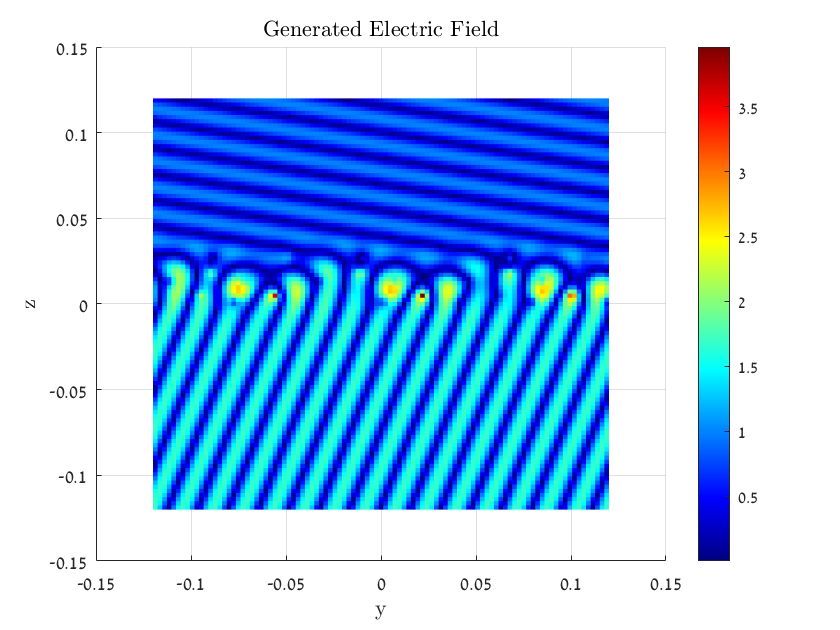


M = 100; %plot resolution
y = linspace(-4*lambda,4*lambda, M)'; % colum vector
z = linspace(-4*lambda,4*lambda, M); % row vector
[TotalElectricFieldMatrix, GeneratedElectricFieldMatrix] = ElectricFieldYZ(best.Is,best.Ds,best.Hs,k,Lambda,y,z,theta_in,Ein,N,eta,theta_out);
PlotField(abs(real(GeneratedElectricFieldMatrix)),y,z,'Generated Electric Field');

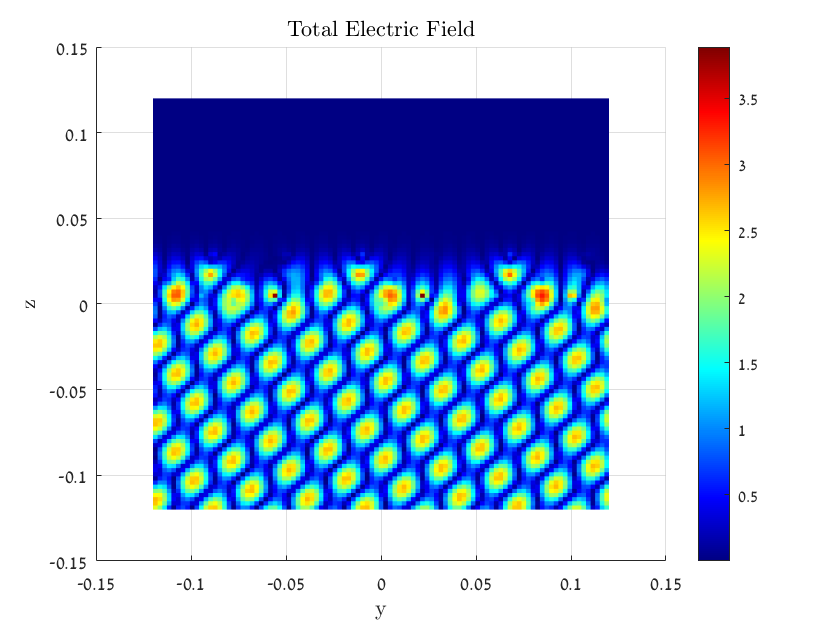

PlotField(abs(real(TotalElectricFieldMatrix)),y,z,'Total Electric Field');

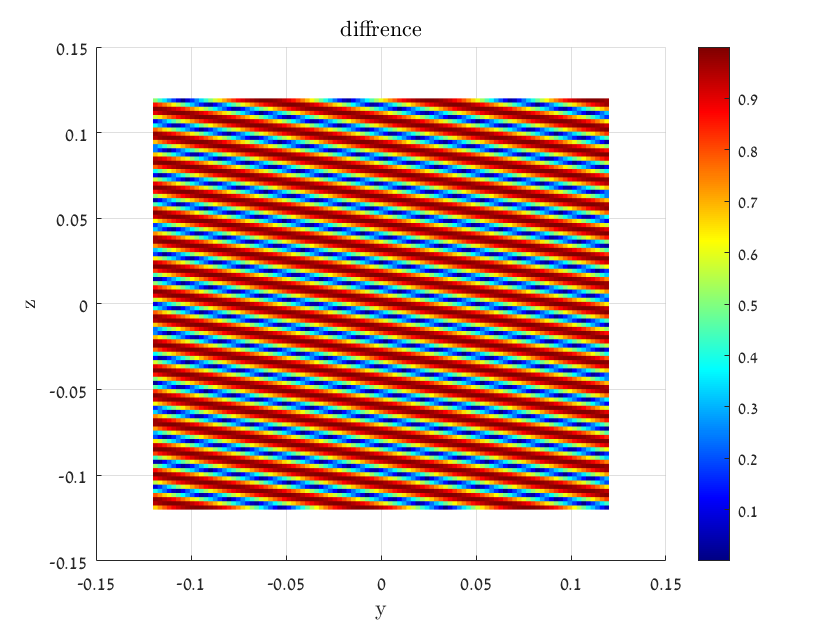

PlotField(abs(real(TotalElectricFieldMatrix-GeneratedElectricFieldMatrix)),y,z,'diffrence');

## normalization

UnitI=lambda/eta*Ein;
IsNorm=best.Is/UnitI;
DsNorm=best.Ds/lambda;
HsNorm=best.Hs/lambda;
PowerIn=1/2/eta*Ein^2*lambda*cosin;
PowerLost=(1/2*abs(best.Is).^2).*real(best.Zs);
NormPowerLost=PowerLost/PowerIn;
NormCopperPowerLost=best.CopperPowerLost./PowerIn;
NormZs=best.Zs*UnitI;

## geomtry coulculator

L=lambda/10;
Cs=-1./(2*pi*f*L*imag(best.Zs));
Ws=(6e10)*Cs;

## finished

[x,Fs] = audioread('sound.wav');
sound(x,Fs);

## optimization function

function f = objectiveFcn(optimInput)

load('var.mat');
% Edit the lines below with your calculation

Ds= [0 optimInput(1:5)];
Hs= [0 optimInput(6:10)];
Is = FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
Zs= Fields./Is;
f= sum(abs((1/2*abs(Is).^2).*real(Zs)))+weigt*sum(abs((1/2*abs(Is).^2).*deltaRes));% minimum power lost (\gain)
%f= sum(abs(real(Zs)./imag(Zs)));
end


## costrains


function [c,ceq] = constraintFcn(optimInput)
load('var.mat');

% Note, if no equality constraints, specify ceq = []
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
D5 = optimInput(4);
D6= optimInput(5);
H2 = optimInput(6);
H3 = optimInput(7);
H4 = optimInput(8);
H5 = optimInput(9);
H6 = optimInput(10);


c(1) = H2 - H3;
c(2) = H3 - H4;
c(3) = H4 - H5;
c(4) = H5 - H6;
c(5) = - H2;
c(6) = - D2;
c(7) = - D3;
c(8) = - D4;
c(9) = - D5;
c(10) = - D6;
c(11) = D2 - Lambda;
c(12) = D3 - Lambda;
c(13) = D4 - Lambda;
c(14) = D5 - Lambda;
c(15) = D6 - Lambda;
c(16) = H6 - lambda;
ceq = [];
end



